1. Загрузите данные **ex7data1.mat **из файла.

load('ex7data1.mat');

2. Постройте график загруженного набора данных.

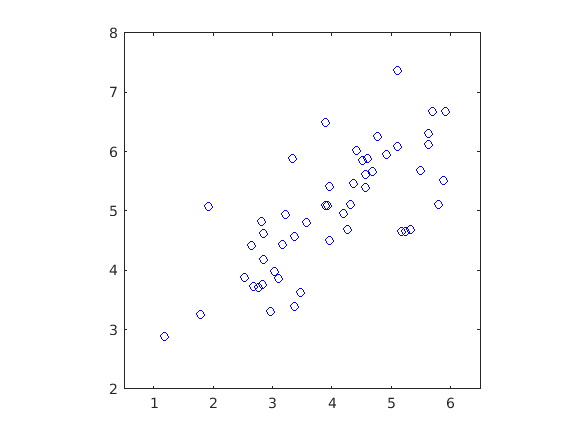

figure;
plot(X(:, 1), X(:, 2), 'bo');
axis([0.5 6.5 2 8]); axis square;

3. Реализуйте функцию вычисления матрицы ковариации данных.

4. Вычислите координаты собственных векторов для набора данных с помощью сингулярного разложения матрицы ковариации (разрешается использовать библиотечные реализации матричных разложений).

5. Постройте на графике из пункта 2 собственные векторы матрицы ковариации.

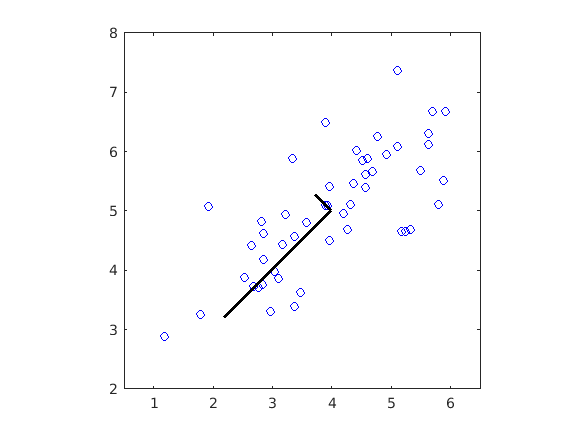

[X_norm, mu, ~] = featureNormalize(X);

[U, S] = pca(X_norm);

hold on;
drawLine(mu, mu + 1.5 * S(1,1) * U(:,1)', '-k', 'LineWidth', 2);
drawLine(mu, mu + 1.5 * S(2,2) * U(:,2)', '-k', 'LineWidth', 2);
hold off;


fprintf('Top eigenvector U(:,1) = %f %f \n', U(1,1), U(2,1));

Top eigenvector U(:,1) = -0.707107 -0.707107 


6. Реализуйте функцию проекции из пространства большей размерности в пространство меньшей размерности с помощью метода главных компонент.

7. Реализуйте функцию вычисления обратного преобразования.

8. Постройте график исходных точек и их проекций на пространство меньшей размерности (с линиями проекций).

% Project the data onto K = 1 dimension
K = 1;
Z = projectData(X_norm, U, K);
fprintf('Projection of the first example: %f\n', Z(1));

Projection of the first example: 1.481274


X_rec  = recoverData(Z, U, K);
fprintf('Approximation of the first example: %f %f\n', X_rec(1, 1), X_rec(1, 2));

Approximation of the first example: -1.047419 -1.047419


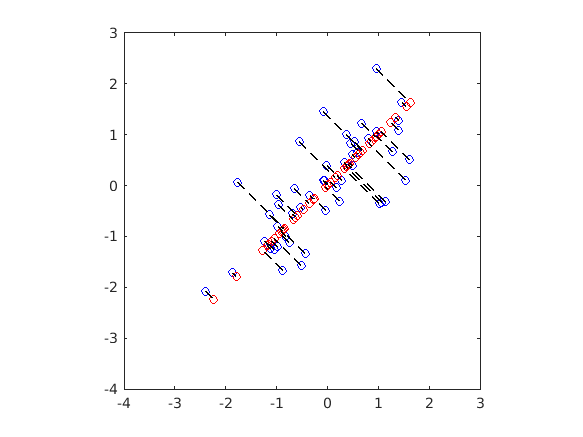

plot(X_norm(:, 1), X_norm(:, 2), 'bo');
axis([-4 3 -4 3]); axis square
hold on;
plot(X_rec(:, 1), X_rec(:, 2), 'ro');
for i = 1:size(X_norm, 1)
    drawLine(X_norm(i,:), X_rec(i,:), '--k', 'LineWidth', 1);
end
hold off

9. Загрузите данные **ex7faces.mat **из файла.

10. Визуализируйте 100 случайных изображений из набора данных.

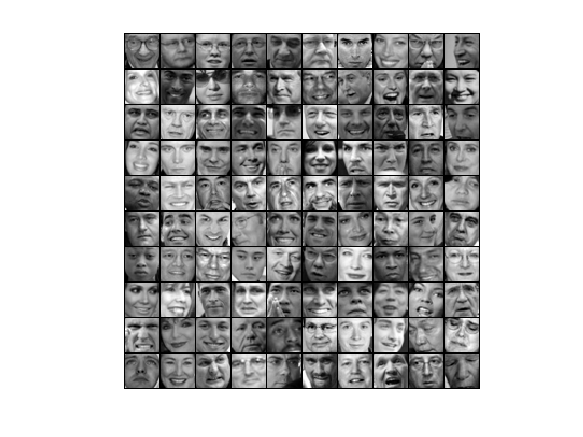

load ('ex7faces.mat')
displayData(X(1:100, :));

11. С помощью метода главных компонент вычислите собственные векторы.

12. Визуализируйте 36 главных компонент с наибольшей дисперсией.

[X_norm, ~, ~] = featureNormalize(X);
[U, ~] = pca(X_norm)

U =    -0.0143   -0.0361   -0.0456    0.0336   -0.0080    0.0470   -0.0289    0.0209   -0.0164    0.0763   -0.0110    0.0238   -0.0129    0.0436   -0.0279    0.0197   -0.0439    0.0207   -0.0106    0.0549   -0.0054    0.0424    0.0367   -0.0615    0.0055    0.0075    0.0168    0.0586   -0.0261   -0.0449    0.0480   -0.0167    0.0198   -0.0310    0.0287   -0.0083    0.0342   -0.0395    0.0222   -0.0141    0.0487   -0.0641    0.0129   -0.1011    0.0563    0.0211   -0.0158    0.0053    0.0223   -0.0327
   -0.0147   -0.0381   -0.0476    0.0334   -0.0071    0.0471   -0.0289    0.0212   -0.0175    0.0801   -0.0086    0.0257   -0.0144    0.0476   -0.0301    0.0195   -0.0412    0.0216   -0.0099    0.0551   -0.0102    0.0448    0.0377   -0.0666    0.0052    0.0103    0.0208    0.0608   -0.0238   -0.0477    0.0484   -0.0171    0.0164   -0.0306    0.0320   -0.0076    0.0323   -0.0392    0.0202   -0.0186    0.0520   -0.0672    0.0181   -0.0962    0.0550    0.0243   -0.0174    0.0076    0.0215   -0

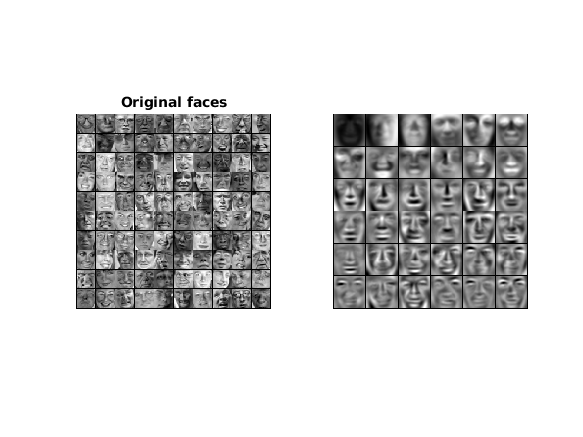

displayData(U(:, 1:36)');

14. Визуализируйте 100 главных компонент с наибольшей дисперсией.

K = 100;
Z = projectData(X_norm, U, K);

fprintf('The projected data Z has a size of: %d x %d', size(Z));

The projected data Z has a size of: 5000 x 100

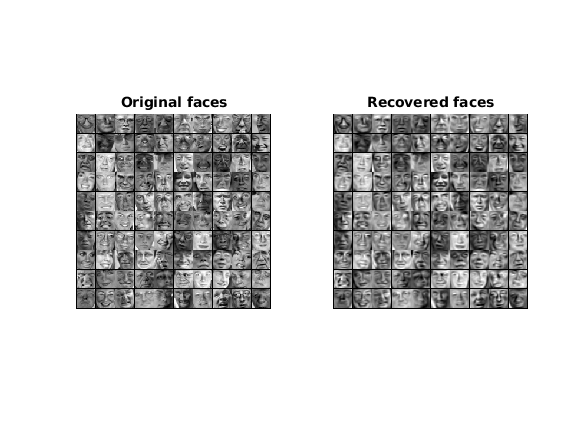

X_rec  = recoverData(Z, U, K);

subplot(1, 2, 1);
displayData(X_norm(1:100,:));
title('Original faces');
axis square;

subplot(1, 2, 2);
displayData(X_rec(1:100,:));
title('Recovered faces');
axis square;

15. Используйте изображение, сжатое в лабораторной работе №6 (Кластеризация).

16. С помощью метода главных компонент визуализируйте данное изображение в 3D и 2D.

clear;
% Re-load the image from the previous exercise and run K-Means on it
% For this to work, you need to complete the K-Means assignment first
A = double(imread('bird_small.png'));
A = A / 255;
img_size = size(A);
X = reshape(A, img_size(1) * img_size(2), 3);
K = 16; 
max_iters = 10;
initial_centroids = kMeansInitCentroids(X, K);
[centroids, idx] = runkMeans(X, initial_centroids, max_iters);

K-Means iteration 1/10...
K-Means iteration 2/10...
K-Means iteration 3/10...
K-Means iteration 4/10...
K-Means iteration 5/10...
K-Means iteration 6/10...
K-Means iteration 7/10...
K-Means iteration 8/10...
K-Means iteration 9/10...
K-Means iteration 10/10...


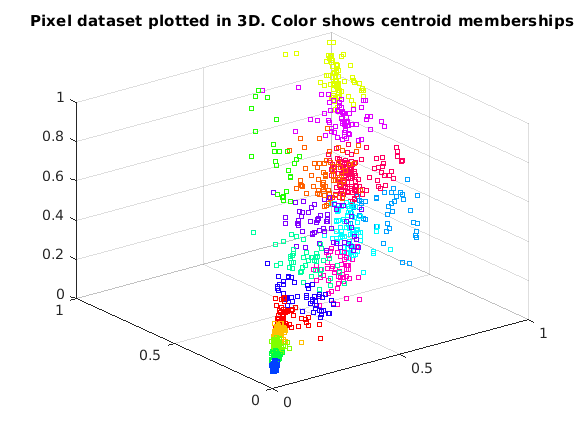


%  Sample 1000 random indexes (since working with all the data is
%  too expensive. If you have a fast computer, you may increase this.
sel = floor(rand(1000, 1) * size(X, 1)) + 1;

%  Setup Color Palette
palette = hsv(K);
colors = palette(idx(sel), :);

%  Visualize the data and centroid memberships in 3D
figure;
scatter3(X(sel, 1), X(sel, 2), X(sel, 3), 10, colors);
title('Pixel dataset plotted in 3D. Color shows centroid memberships');

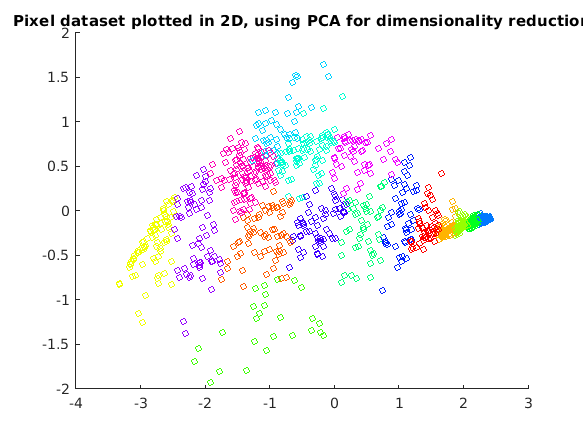

% Subtract the mean to use PCA
[X_norm, mu, sigma] = featureNormalize(X);

% PCA and project the data to 2D
[U, S] = pca(X_norm);
Z = projectData(X_norm, U, 2);

% Plot in 2D
figure;
plotDataPoints(Z(sel, :), idx(sel), K);
title('Pixel dataset plotted in 2D, using PCA for dimensionality reduction');